clear all

### Material properties

The code begins by defining the material properties of structural steel,

% E: modulus of elasticity
E = 69*10^9;%200*10^9;
% A: area of cross section
A = 30*10-4;%15*10-4;
% EA: axial stiffness
EA = E*A; 
% rho: density
rho = 2700;%7850; 
% rhoA: mass per unit length 
rhoA = rho*A;
% Applied force 
f = 50000; 

### **Geometry and mesh connectivity**

The truss geometry is defined through a node coordinate matrix and a connectivity matrix. The nodes are arranged in a simple triangular configuration, and elements are formed between nodes via the connectivity table. A plotting function (`draw2Dtruss`) is used to visually confirm the mesh.

%                    1    2    3    4    5    6    7    8    9      10   11                 11 
nodesCoordinates = [0 0; 1 0; 2 0; 1 1; 2 2; 3.5 1; 5 0; 5 2; 6.5 1; 8 0; 8 2;
%                   12      13    14      15      16    17    18      19
                     9.5 1; 11 0; 11 2;  12.5 1; 14 0; 14 2; 15.5 1; 17 0;
%                     20    21     22      23   24   25    26 
                     17 2; 18.5 1; 20 0; 20 2;21 1; 21 0; 22 0];

connectivity = [1 2; 1 4; 2 4; 2 3; 4 3; 4 5; 5 3; 5 8; 5 6; 3 6; 3 7; 6 7; 6 8; 8 11; 8 9; 8 7
                7 9; 7 10; 9 11; 9 10; 11 14; 11 12; 11 10; 10 12; 10 13; 12 14; 12 13;
                14 17; 14 15; 14 13; 13 15; 13 16; 15 17; 15 16; 17 20; 17 18; 17 16; 16 18; 16 19; 18 20; 18 19;
                20 23; 20 21; 20 19; 19 21 ; 19 22; 21 23; 21 22; 23 24; 23 22; 22 24; 22 25; 24 26; 24 25; 25 26]

connectivity =      1     2
     1     4
     2     4
     2     3
     4     3
     4     5
     5     3
     5     8
     5     6
     3     6


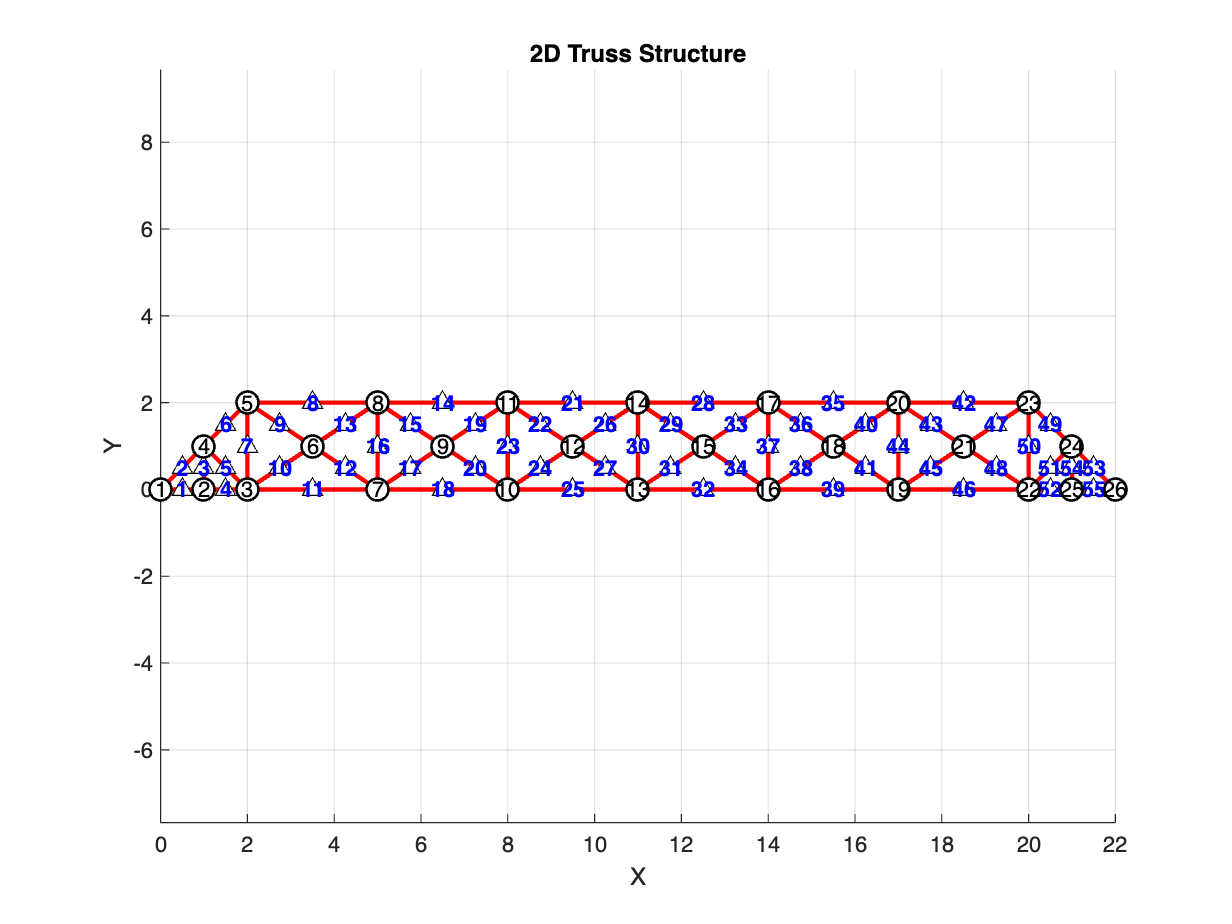


                % 14 15; 14 13; 13 15; 13 16; 15 16; 15 17; 16 17];

numberOfNodes = size(nodesCoordinates,1);

GDof = 2*numberOfNodes;

draw2Dtruss(nodesCoordinates, connectivity, ...
    'LineColor', 'r', ...
    'LineWidth', 2, ...
    'MarkerSize', 10, ...
    'FontSize', 10, ...
    'ShowNodeNumbers', true);

[n, dim] = size(nodesCoordinates);

L = 0;
for e=1:n
    x = nodesCoordinates(connectivity(e,:),:);
    l{e} = sqrt(sum((x(2,:)-x(1,:)).^2));
    L = L + l{e};
end

Steel_max = 1/(15e-4)

Steel_max = 666.6667

Steel_min = 1/(50e-4)

Steel_min = 200

Wood_max = 2/(30e-4)

Wood_max = 666.6667

Wood_min = 2/(100e-4)

Wood_min = 200

L

L = 51.0732

### Global stiffness and consistent mass matrices

The next step involves the computation of the global stiffness matrix and global consistent mass matrix using helper functions (`formStiffness2Dtruss` and `formConsistentMass2Dtruss`). These matrices represent the elastic and inertial properties of the system, respectively, and are assembled in the global coordinate system based on the element-level contributions.

% compute and assemble the structure stiffness matrix
stiffness = formStiffness2Dtruss(GDof, connectivity, nodesCoordinates, EA);

% compute and assemble the structure maass matrix
mass = formConsistentMass2Dtruss(GDof,connectivity, nodesCoordinates, rhoA);

### **Applying boundary conditions and solving the eigenproblem**

Boundary conditions are applied by specifying the degrees of freedom (DOFs) that are constrained. In this case, node 1 is fully fixed (both DOFs), and node 4 is constrained in the y-direction, leading to three free DOFs in the system. The stiffness and mass matrices are reduced accordingly to consider only the unconstrained DOFs.

prescribedDof = transpose([1:4 length(connectivity(:,1))-3:length(connectivity(:,1))]);

activeDof = setdiff(transpose((1:GDof)), prescribedDof);
stiffness_freeDofs = stiffness(activeDof,activeDof);
mass_freeDofs = mass(activeDof,activeDof);

### **Static analysis **

force = zeros(length(connectivity(:,1))-8,1); 
force(26) = -f; 

displacements = stiffness_freeDofs\force;

disp(max(displacements))

   5.0893e-08



### **Dynamic analysis **

[modal_matrix,frequencies] = computeFrequenciesAndModes(GDof,prescribedDof,stiffness,mass,0);

disp(frequencies(1)/(2*pi))

   21.4672

